# 5 bars painting robot

### Robot characteristic

%Definizione delle caratteristiche del robot
clc 
clear all
close all
set(0, 'DefaultFigureRenderer', 'painters');
load_robot_specs

P1 = [-0.5 0.75 h-0.2]; % Home position
P2 = [-0.25 1.1 h-0.1];
P3 = [-0.25 1.1 h-0.7];


### 1) P1 to P2

dS = norm(P2-P1);
[T_alfa,l1_alfa,l3_alfa] = minActuationTime(acc_limits(1,1),acc_limits(1,2),vel_limits(1,1),dS);
[T_beta,l1_beta,l3_beta] = minActuationTime(acc_limits(1,3),acc_limits(1,4),vel_limits(1,3),dS);
[T_rho,l1_rho,l3_rho] = minActuationTime(acc_limits(1,5),acc_limits(1,6),vel_limits(1,5),dS);

switch max([T_alfa T_beta T_rho])
    case T_alfa
        T=T_alfa; lamda1=l1_alfa; lamda3=l3_alfa;
    case T_beta
        T=T_beta; lamda1=l1_beta; lamda3=l3_beta;
    case T_rho
        T=T_rho;  lamda1=l1_rho;  lamda3=l3_rho;
end

n = 50;
dT = T /(n-1);

Q_1 = inverse_kinematics(P1,L,[130*pi/180 50*pi/180]);
Q_2 = inverse_kinematics(P2,L,[130*pi/180 50*pi/180]);

dQ = Q_2 - Q_1;

for i = 1:n
    t = (i-1)*dT;
    tt_1(i) = t;
    [q_1(i,:) qp_1(i,:) qpp_1(i,:)] = tretratti(t,T,Q_1,dQ,lamda1,lamda3);
    if i==1; guess = [0 80]; else; guess = s_1(i-1,:); end
    s_1(i,:) = direct_kinematics(q_1(i,:),L,guess); 
    [J, J_s, J_q] = Jacobian(s_1(i,1:2),q_1(i,1:2),L);
    v_1(i,:) = inv(J)*qp_1(i,1:2)';
    a_1(i,:) = -inv(J_s)*(Jp_s(q_1(i,1:2),qp_1(i,1:2),v_1(i,:),L)*v_1(i,:)'+Jp_q(s_1(i,:),q_1(i,1:2),qp_1(i,1:2),v_1(i,:),L)*qp_1(i,1:2)'+J_q*qpp_1(i,1:2)');
end

v_1(:,3)=qp_1(:,3);
a_1(:,3)=qpp_1(:,3);

Fq_1 = torque_evaluation(q_1,qp_1,qpp_1,J,dT,L,G,M,Fse,n,1);

### 2) Circular trajectory

R = 0.5; dH = 0.1;
P0 = [l0/2 1.1 h-0.1]; % Centro del pezzo da lavorare
v_cost = 0.5;
[s_2, v_2, a_2, dt] = trajectory_planning(R,dH,50,P0,v_cost);

for i = 1:1:length(s_2)
    if i==1
        guess = [130*pi/180 50*pi/180];
    else
        guess = q_2(i-1,:);
    end
    q_2(i,:) = inverse_kinematics(s_2(i,:),L,guess); 
    [J, J_s, J_q] = Jacobian(s_2(i,:),q_2(i,:),L);
    qp_2(i,:) = J*v_2(i,1:2)';
    qpp_2(i,:) = -inv(J_q)*((Jp_s(q_2(i,:),qp_2(i,:),v_2(i,1:2),L)*v_2(i,1:2)'+J_s*a_2(i,1:2)'+Jp_q(s_2(i,:),q_2(i,:),qp_2(i,:),v_2(i,1:2),L)*qp_2(i,:)'));    
end

qp_2(:,3)=v_2(:,3);
qpp_2(:,3)=a_2(:,3);

Fq_2 = torque_evaluation(q_2,qp_2,qpp_2,J,dt,L,G,M,Fse,350,2);

dt = horzcat(tt_1(end),dt);
tt_2=dt;
for i=2:length(dt)
    tt_2(i)=tt_2(i)+tt_2(i-1);
end

tt = horzcat(tt_1,tt_2);

### 3) P3 to P1

dS = norm(P3-P1);
[T_alfa,l1_alfa,l3_alfa] = minActuationTime(acc_limits(1,1),acc_limits(1,2),vel_limits(1,1),dS);
[T_beta,l1_beta,l3_beta] = minActuationTime(acc_limits(1,3),acc_limits(1,4),vel_limits(1,3),dS);
[T_rho,l1_rho,l3_rho] = minActuationTime(acc_limits(1,5),acc_limits(1,6),vel_limits(1,5),dS);

switch max([T_alfa T_beta T_rho])
    case T_alfa
        T=T_alfa; lamda1=l1_alfa; lamda3=l3_alfa;
    case T_beta
        T=T_beta; lamda1=l1_beta; lamda3=l3_beta;
    case T_rho
        T=T_rho;  lamda1=l1_rho;  lamda3=l3_rho;
end

n = 50;
dT = T/(n-1);

Q_1 = inverse_kinematics(P3,L,[130*pi/180 50*pi/180]);
Q_2 = inverse_kinematics(P1,L,[130*pi/180 50*pi/180]);

dQ = Q_2 - Q_1;

for i = 1:n
    t = (i-1)*dT;
    tt_3(i) = t;
    [q_3(i,:) qp_3(i,:) qpp_3(i,:)] = tretratti(t,T,Q_1,dQ,lamda1,lamda3);
    if i==1; guess = [0 80]; else; guess = s_3(i-1,:); end
    s_3(i,:) = direct_kinematics(q_3(i,:),L,guess);
    [J, J_s, J_q] = Jacobian(s_1(i,1:2),q_1(i,1:2),L);
    v_3(i,:) = inv(J)*qp_3(i,1:2)';
    a_3(i,:) = -inv(J_s)*(Jp_s(q_3(i,1:2),qp_3(i,1:2),v_3(i,:),L)*v_3(i,:)'+Jp_q(s_3(i,:),q_3(i,1:2),qp_3(i,1:2),v_3(i,:),L)*qp_3(i,1:2)'+J_q*qpp_3(i,1:2)');
        
end

Fq_3 = torque_evaluation(q_3,qp_3,qpp_3,J,dT,L,G,M,Fse,n,1);

tt_3 = tt_3+tt(end);
v_3(:,3)=qp_3(:,3);
a_3(:,3)=qpp_3(:,3);

### 4) Sum of 3 pieces

q = vertcat(q_1,q_2,q_3);
qp = vertcat(qp_1,qp_2,qp_3);
qpp = vertcat(qpp_1,qpp_2,qpp_3);
s = vertcat(s_1,s_2,s_3);
v = vertcat(v_1,v_2,v_3);
a = vertcat(a_1,a_2,a_3);
tt = horzcat(tt,tt_3);
Fq = vertcat(Fq_1,Fq_2,Fq_3);

save trajectory_data.mat q qp qpp tt s v a Fq
disp('Salvataggio traiettoria completato')

Salvataggio traiettoria completato


### 3D Plot

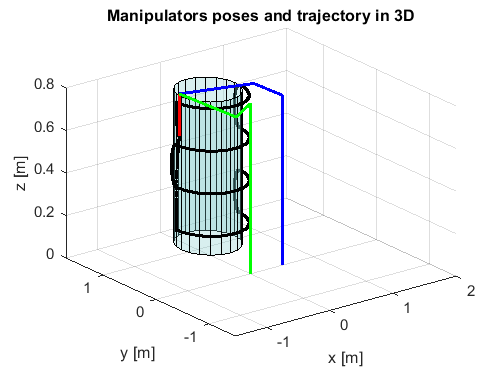

dt_pause=0.02;
close all
figure(2)

r = 0.42;
[X,Y,Z] = cylinder(r);
Z = Z*(h-0.08);
surf(X+0.25,Y+1.1,Z,'FaceColor', [0.5,0.8,0.8]);
alpha(0.3)
xlim([-l1-l2,l0+l1+l2]);
ylim([-l1-l2,l1+1.2*l2]);
zlim([0,h]);

xlabel('x [m]')
ylabel('y [m]')
zlabel('z [m]')
title('Manipulators poses and trajectory in 3D');
grid on

for i=1:length(s)
    % Print
    [config1, theta(i)] = Plot3D_1st(q(i,:),L,2,s(i,1),s(i,2));
    [config2, gamma(i)] = Plot3D_2nd(q(i,:),L,2,s(i,1),s(i,2));
    config3 = Plot3D_3rd(L,2,s(i,1),s(i,2),s(i,3));
    plot3(s(i,1),s(i,2),s(i,3),'.-black');
    
    pause(dt_pause)
    if i==length(s)
        break
    end
    delete(config1); delete(config2); delete(config3)
end

hold off

### 1a) Print $\alpha ,\beta ,\gamma \;$and $\theta$

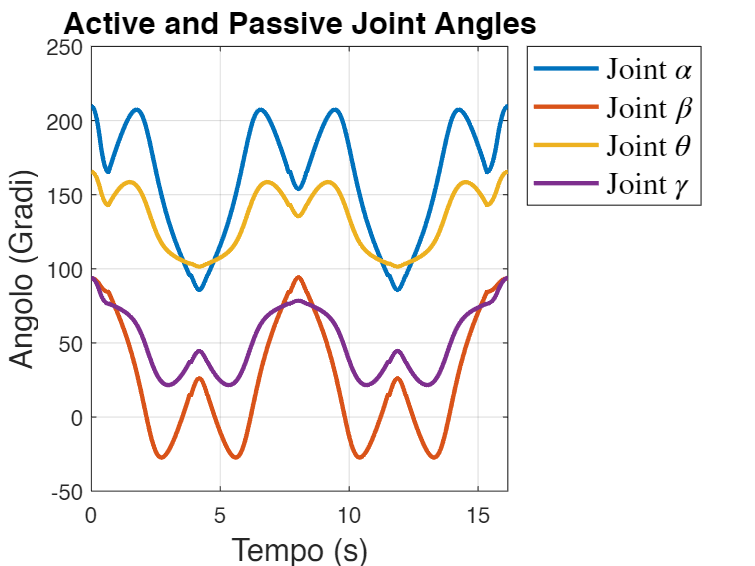

figure(3)
% alpha e beta
plot(tt,q(:,1)*180/pi,'LineWidth',2); hold on
plot(tt,q(:,2)*180/pi,'LineWidth',2); hold on
plot(tt,gamma*180/pi,'LineWidth',2);hold on
plot(tt,theta*180/pi,'LineWidth',2); hold off
title('Active and Passive Joint Angles',FontSize=14);
xlabel('Tempo (s)',FontSize=14);
ylabel('Angolo (Gradi)',FontSize=14);
grid on
xlim([0 tt(end)]);
h_legend=legend('Joint $\alpha$','Joint $\beta$','Joint $\theta$','Joint $\gamma$');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);

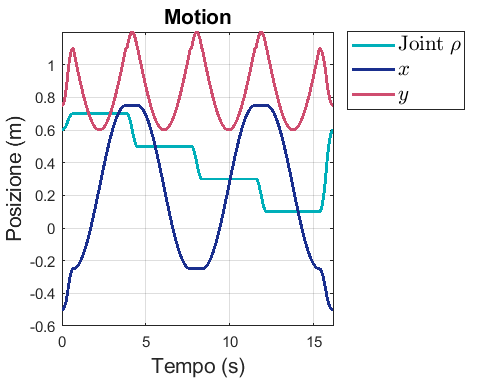



% rho
figure(4)
plot(tt,q(:,3),'Color',[0, 0.6863, 0.7255],'LineWidth',2); hold on
plot(tt,s(:,1),'Color',[0.1 0.1840 0.5560],'LineWidth',2); hold on
plot(tt,s(:,2),'Color',[0.8118, 0.3020, 0.4353],'LineWidth',2); hold off
title('Motion',FontSize=14);
xlabel('Tempo (s)',FontSize=14);
ylabel('Posizione (m)',FontSize=14);
grid on
xlim([0 tt(end)]);
h_legend=legend('Joint $\rho$','$x$','$y$');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);

### 1b) Velocities and accelerations

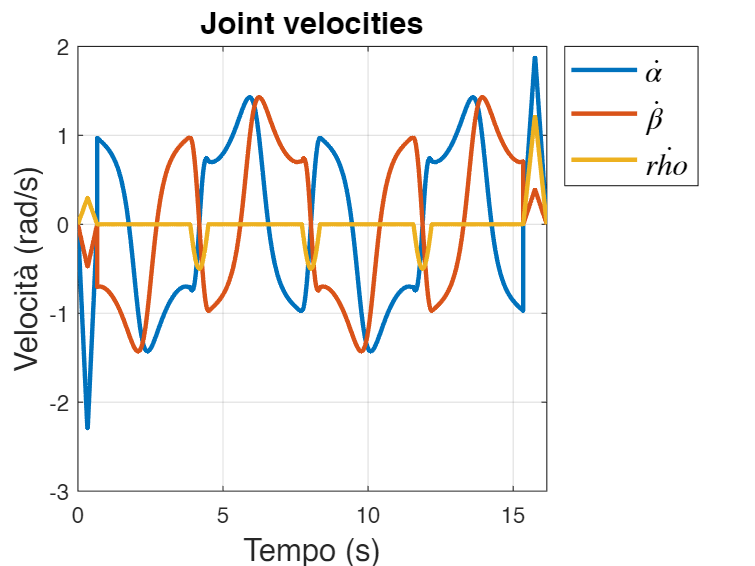

% Joint
close all
figure(7)
plot(tt,qp(:,1),LineWidth=2); hold on
plot(tt,qp(:,2),LineWidth=2); hold on
plot(tt,qp(:,3),LineWidth=2); hold on


h_legend=legend('$\dot{\alpha}$','$\dot{\beta}$','$\dot{rho}$');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);
title('Joint velocities',FontSize=14);
xlabel('Tempo (s)',FontSize=14)
ylabel('Velocità (rad/s)',FontSize=14)
grid on
xlim([0 tt(end)]);

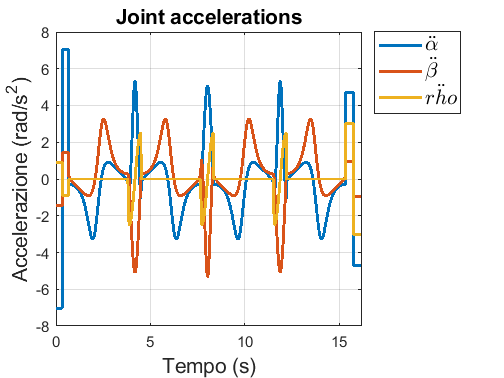


figure(8)
plot(tt,qpp(:,1),LineWidth=2); hold on
plot(tt,qpp(:,2) ,LineWidth=2); hold on
plot(tt,qpp(:,3) ,LineWidth=2); hold on
xlim([0 tt(end)]);
h_legend=legend('$\ddot{\alpha}$','$\ddot{\beta}$','$\ddot{rho}$');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);
title('Joint accelerations',FontSize=14);
xlabel('Tempo (s)',FontSize=14)
ylabel('Accelerazione (rad/s^2)',FontSize=14)
grid on

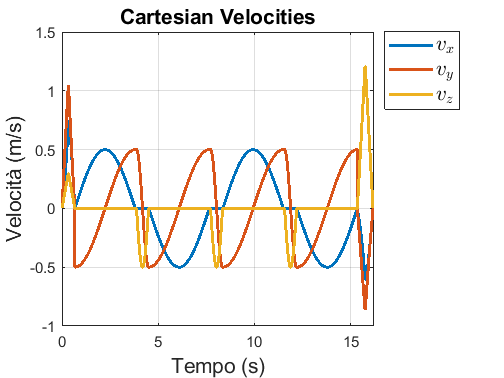


% Cartesian
figure(9)
plot(tt,v(:,1),LineWidth=2); hold on
plot(tt,v(:,2),LineWidth=2); hold on
plot(tt,v(:,3),LineWidth=2); hold on
xlim([0 tt(end)]);
h_legend=legend('$v_x$','$v_y$','$v_z$');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);
title('Cartesian Velocities',FontSize=14);
xlabel('Tempo (s)',FontSize=14)
ylabel('Velocità (m/s)',FontSize=14)
grid on

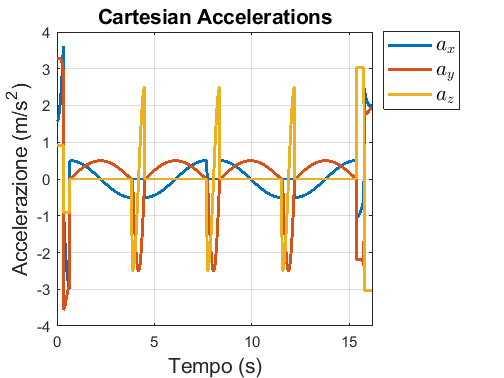


figure(10)
plot(tt,a(:,1),LineWidth=2); hold on
plot(tt,a(:,2),LineWidth=2); hold on
plot(tt,a(:,3),LineWidth=2); hold on
xlim([0 tt(end)]);
h_legend=legend('$a_x$','$a_y$','$a_z$');
set(h_legend, 'location', 'northeastoutside')
set(h_legend,'Interpreter','latex');
set(h_legend,'FontSize',14);
title('Cartesian Accelerations',FontSize=14);
xlabel('Tempo (s)',FontSize=14)
ylabel('Accelerazione (m/s^2)',FontSize=14)
grid on